# Pendulum Linear ID

load('signal_2c_1_6.mat')
y = pendulum_angle.data;
y = y(2:end);

a3_0 = 11.2217;
a4_0 = 0.2380;

theta = [a3_0 a4_0 0 0]';
lambda = 0.001;
maxiter = 500;
p = 4;
h = 0.01;
converged = false;
maxiter_reached = false;
iter = 1;

B = [0; 0];
C = [1 0];
D = 0;

while ~converged && ~maxiter_reached 

    [Abar, x0] = theta2matrices(theta, h);
    [yhat, xhat] = simsystem(Abar, B, C, x0, u);
    E = y - yhat;
    psi = psi_fun(xhat, x0, Abar, h);
    N_E = length(E);
    J = 2/N_E * psi' * E; % Jacobian
    N_H = size(psi,1);
    H = 2/N_H * (psi' * psi); % Hessian

    invLM = (H + lambda * eye(p))\eye(p); %Levenberg-Marquardt singularity inverse
    theta_new = theta - invLM * J;
    
    % Check convergence
    if norm(theta_new - theta) < 1e-6
        converged = true; 
    elseif iter == maxiter 
        maxiter_reached = true; 
        warning('Maximum iterations reached'); 
    end
    theta = theta_new; 
    iter = iter + 1;
end

A = Abar;
a3 = theta(1);
a4 = theta(2);
x0 = theta(3:4);


## Validation

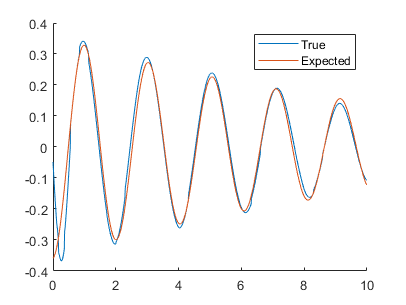

t = 0:h:(length(u)*h)-h;
figure;
hold on
plot(t,y);
[yhat,xhat] = simsystem(A, 0, C, x0, u);
plot(t,yhat);

legend("True", "Expected")

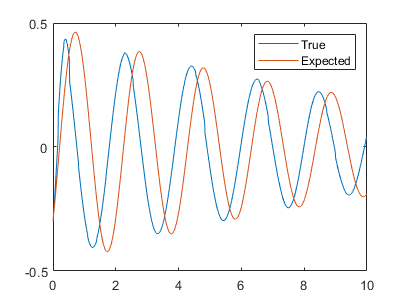


% Verification data
load('signal_2b_1_6.mat')
t = 0:h:(length(u)*h)-h;
y = pendulum_angle.data;
y = y(2:end);
[yhat,xhat] = simsystem(A,0,C,[y(1), 1*(y(2)-y(1))/h], u);
figure;
plot(t,y);
hold on
plot(t,yhat);
legend("True", "Expected")

## Functions

function [Abar,x0] = theta2matrices(theta,h)

a3 = theta(1); a4 = theta(2); x0 = theta(3:4);

Abar=[1 h; -a3*h 1-a4*h]; 
end

function psi = psi_fun(xhat, x0, Abar,h)

C = [1 0];
% Dimensions
n = 2; l = 1;

% Derivative Definitions
dAbar1 = [0 0; -h 0];
dAbar2 = [0 0; 0 -h];

dx03 = [1; 0];
dx04 = [0; 1];  

N = size(xhat,2); 
p = 4; % 11 sub-parameters of theta
% xhat = xhat'; % x coming in is Nxn, now is nxN

dx = zeros(n,p);
dy = zeros(l,p);
psi = zeros((N-1)*l,p);

% First iteration
dx1 = dAbar1*x0;
dx2 = dAbar2*x0;

dx=[dx1 dx2 dx03 dx04];
for k = 2:N % xhat is 0 - N-1, 
    % dy / psi update
    for i = 1 : p
        dy(:,i) = C * dx(:,i);
    end
    psi((k-l)*l+1:(k-l)*l+l,:) = -dy; % psi is relative to -dyhat
    psi((k-2)*l+1:(k-1)*l,:) = -dy;

    % dx update
    % A parameters
    dx(:,1) = Abar * dx(:,1) + dAbar1 * xhat(:,k);
    dx(:,2) = Abar * dx(:,2) + dAbar2 * xhat(:,k);

    % x0 parameters
    dx(:,3) = Abar * dx(:,3);
    dx(:,4) = Abar * dx(:,4);

end
% psi = [zeros(2,p) ; psi]; % How to deal with dyhat0?
end